# サッカー　Eloレーティングから3値出力モデルを構築する

clear;clc;close all;

データの読み込みと前処理

tbl=readtable('../../data/archive/results.csv','encoding','UTF-8');
teamNames=unique([tbl.home_team;tbl.away_team]);
tbl.home_team=categorical(tbl.home_team,teamNames);
tbl.away_team=categorical(tbl.away_team,teamNames);
teamNames=categorical(teamNames);
tbl.tournament=categorical(tbl.tournament);
tbl.neutral=str2mat(tbl.neutral);


Eloレーティング算出(ホームアドバンテージを考慮しない)

それぞれの試合で更新前のレーティング値を記録する

EloA=zeros(size(tbl,1),1);
EloB=zeros(size(tbl,1),1);

r=zeros(size(teamNames));
K=log(10)/400*32

K = 0.1842

for n1=1:size(tbl,1)
    taName=tbl.home_team(n1);
    tbName=tbl.away_team(n1);
    taNum=find(teamNames==taName);
    tbNum=find(teamNames==tbName);
    
    EloA(n1)=r(taNum);
    EloB(n1)=r(tbNum);

    taGoals=tbl.home_score(n1);
    tbGoals=tbl.away_score(n1);

    % 結果
    if taGoals>tbGoals
        s=1;
    elseif taGoals==tbGoals
        s=0.5;
    else
        s=0;
    end

    % 予測勝率
    taRating=r(taNum);
    tbRating=r(tbNum);

    p=1./(1+exp(tbRating-taRating));
    r(taNum)=r(taNum)+K*(s-p);
    r(tbNum)=r(tbNum)-K*(s-p);
    
end

試合前のレーティング値をtblに追加

tbl=addvars(tbl, EloA,EloB);
tbl=addvars(tbl, EloA-EloB,'NewVariableNames','RateDiff');

3値モデル構築に使うデータ範囲を指定

endDate=datetime(2022,11,1);
startDate=endDate-years(4);
ind= tbl.date>startDate & tbl.date<endDate;
tbl_train=tbl(ind,:);
rateDiff=[tbl_train.RateDiff;-tbl_train.RateDiff];
goalDiff=[tbl_train.home_score-tbl_train.away_score];
goalDiff=[goalDiff;-goalDiff];

ind_win=goalDiff>0;
ind_draw=goalDiff==0;
ind_lose=goalDiff<0;

3値モデルの構築

mdl(1,:)=glmfit(rateDiff, ind_lose,'binomial','link','logit');
mdl(2,:)=glmfit(rateDiff, ind_lose|ind_draw,'binomial','link','logit');

図示

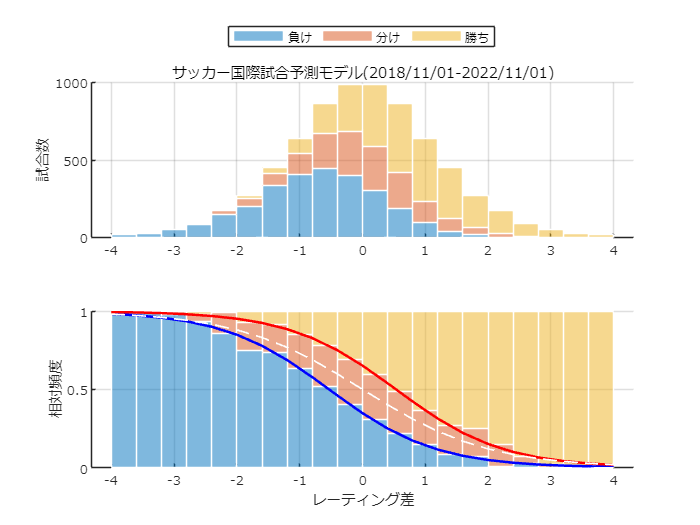

figure
hold on;
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
title(['サッカー国際試合予測モデル(' ...
    datestr(startDate,'yyyy/mm/dd') '-' ...
    datestr(endDate,'yyyy/mm/dd') ')'])
bins=(-1:0.1:1)*4;
hCounts=[histcounts(rateDiff(ind_lose),bins);
    histcounts(rateDiff(ind_draw),bins);
    histcounts(rateDiff(ind_win),bins)]; %各階級の度数
bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('試合数');
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
xlabel('レーティング差');
ylabel('相対頻度');
plot(bins, glmval(mdl(1,:)',bins,"logit"),'b-','LineWidth',1.5);
plot(bins, glmval(mdl(2,:)',bins,"logit"),'r-','LineWidth',1.5);
plot(bins, 1-1./(1+exp(-bins)),'w--','LineWidth',1);

exportgraphics(gcf,'fig_InternationalFootball_multiOutHist.pdf');

予測モデルの検証

予測モデル構築後のデータをテストデータとする

ind = tbl.date>endDate;
tbl_test=tbl(ind,:);

rateDiff=[tbl_test.RateDiff;-tbl_test.RateDiff];
pWin=1./(1+exp(-rateDiff));
goalDiff=[tbl_test.home_score-tbl_test.away_score];
goalDiff=[goalDiff;-goalDiff];

ind_win=goalDiff>0;
ind_draw=goalDiff==0;
ind_lose=goalDiff<0;
ind_s=pWin>0.5;

pWin=pWin(ind_s);
ind_win=ind_win(ind_s);
ind_draw=ind_draw(ind_s);
ind_lose=ind_lose(ind_s);
goalDiff=goalDiff(ind_s);

較正値の算出

[予測勝率の合計　実際の(勝利数)+(引き分け数)/2]

[sum(pWin) (sum(ind_win)+0.5*sum(ind_draw))]

ans = 1.0e+03 *

    1.4472    1.4575


calibVal=sum(pWin)/(sum(ind_win)+0.5*sum(ind_draw))

calibVal = 0.9929


figure
hold on;
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
title(['サッカー国際試合予測モデル検証(' ...
    datestr(endDate,'yyyy/mm/dd') '-' ...
    datestr(max(tbl_test.date),'yyyy/mm/dd') ')'])
bins=0.5:0.05:1;
hCounts=[histcounts(pWin(ind_lose),bins);
    histcounts(pWin(ind_draw),bins);
    histcounts(pWin(ind_win),bins)]; %各階級の度数

aRatio=(hCounts(3,:)+hCounts(2,:)/2)./sum(hCounts)

aRatio =     0.5377    0.6301    0.6128    0.6813    0.7500    0.7356    0.8119    0.8701    0.9280    0.9796


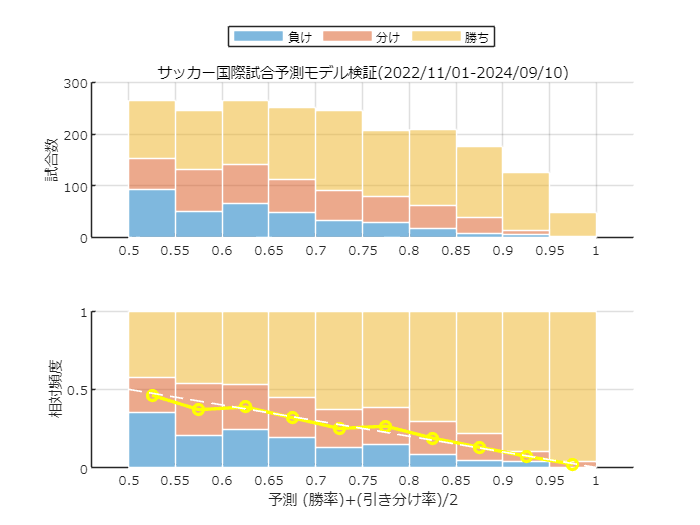


bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('試合数');
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
xlabel('予測 (勝率)+(引き分け率)/2');
ylabel('相対頻度');
plot(movmean(bins,2,'Endpoints','discard'), 1-aRatio, 'yo-','LineWidth',2)
plot(bins, 1-bins,'w--','LineWidth',1);
exportgraphics(gcf,'fig_InternationalFootball_multiOutHist_testPerformance.pdf');

save predictionModel.mat
